# Inductance Estimation from Measurement

Performed test:

A resistor is soldered in series to the DC motor (including filtering on PCB and wires).

1Vpp square wave @2kHz (50% duty cycle) is applied.

- Channel 1: signal generator output;

- Channel 2: node between resistor and motor

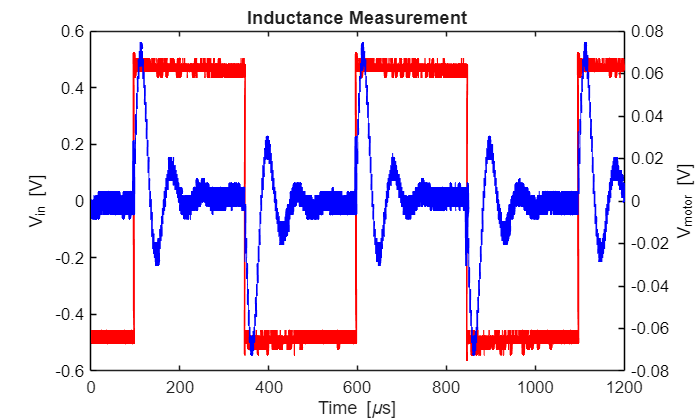

filename = "scope_capture.csv";
data = readmatrix(filename);

t = data(:, 1);
ch1 = data(:, 2);
ch2 = data(:, 3);

fig=figure;
set(fig,'defaultAxesColorOrder',[[0 0 0]; [0 0 0]]);
yyaxis("left");
plot(t,ch1,Color="r",LineWidth=2,DisplayName="Input"); hold on;
ylabel('V_{in} [V]');
yyaxis("right");
ylabel('V_{motor} [V]');
plot(t,ch2,Color="b",LineWidth=2,DisplayName="Motor");
xlabel('Time [\mus]')
title("Inductance Measurement");